% Initialize arrays with new dimensions
imgs_train  = zeros(376, 512, 3, 253, 'single');
resps_train = zeros(376, 512, 3, 253, 'single');

for ind = 1:253
    % Read the image data using imread
    img_input = imread("New radar dataset/train/Input/Clutter ("+ind+").png");
    img_output = imread("New radar dataset/train/Output/noClutter ("+ind+").png");
    
    % Resize the images
    img_input_resized = imresize(img_input, [376, 512]);
    img_output_resized = imresize(img_output, [376, 512]);
    
    % Convert to single precision and store in the corresponding slice
    imgs_train(:,:,:,ind) = im2single(img_input_resized);
    resps_train(:,:,:,ind) = im2single(img_output_resized);
end

% Initialize arrays with new dimensions
imgs_val  = zeros(376, 512, 3, 92, 'single');
resps_val = zeros(376, 512, 3, 92, 'single');

for ind = 1:55
    % Read the image data using imread
    img_input = imread("New radar dataset/validation/Input/Clutter ("+ind+").png");
    img_output = imread("New radar dataset/validation/Output/noClutter ("+ind+").png");
    
    % Resize the images
    img_input_resized = imresize(img_input, [376, 512]);
    img_output_resized = imresize(img_output, [376, 512]);
    
    % Convert to single precision and store in the corresponding slice
    imgs_val(:,:,:,ind) = im2single(img_input_resized);
    resps_val(:,:,:,ind) = im2single(img_output_resized);
end


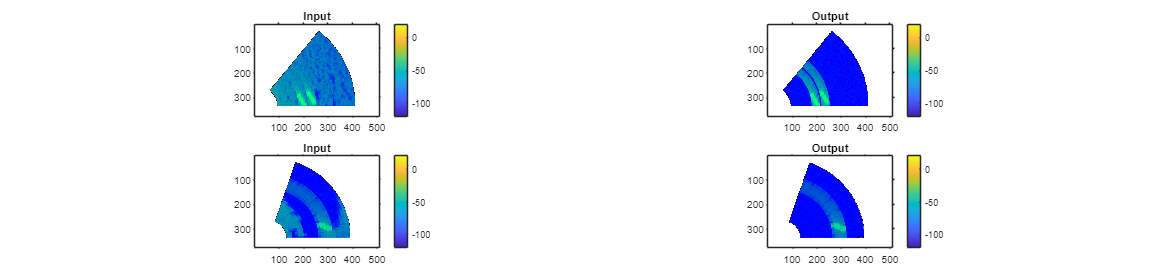

fh = figure;
    fh.Color = 'white';
    
    subplot(2,2,1)
    image = imgs_train(:,:,:,228);
    % Find pixels where all RGB values are 0\
    black_pixels = all(image == 0, 3);
    
    % Create a mask for replacing black pixels
    mask = cat(3, black_pixels, black_pixels, black_pixels);
    
    % Replace black pixels with 1 1 1
    image(mask) = 1;

    imshow(image);
    clim([-120 20])
    colorbar
    axis on
    axis equal
    axis tight
    title('Input')
    
    subplot(2,2,2)
    image = resps_train(:,:,:,228);
    % Find pixels where all RGB values are 0\
    black_pixels = all(image == 0, 3);
    
    % Create a mask for replacing black pixels
    mask = cat(3, black_pixels, black_pixels, black_pixels);
    
    % Replace black pixels with 1 1 1
    image(mask) = 1;
    imshow(image);
    clim([-120 20])
    colorbar
    axis on
    axis equal
    axis tight
    title('Output')
    fh.Position = fh.Position + [0 0 600 0];

    subplot(2,2,3)
    image = imgs_train(:,:,:,140);
    % Find pixels where all RGB values are 0\
    black_pixels = all(image == 0, 3);
    
    % Create a mask for replacing black pixels
    mask = cat(3, black_pixels, black_pixels, black_pixels);
    
    % Replace black pixels with 1 1 1
    image(mask) = 1;

    imshow(image);
    clim([-120 20])
    colorbar
    axis on
    axis equal
    axis tight
    title('Input')
    
    subplot(2,2,4)
    image = resps_train(:,:,:,140);
    % Find pixels where all RGB values are 0\
    black_pixels = all(image == 0, 3);
    
    % Create a mask for replacing black pixels
    mask = cat(3, black_pixels, black_pixels, black_pixels);
    
    % Replace black pixels with 1 1 1
    image(mask) = 1;
    imshow(image);
    clim([-120 20])
    colorbar
    axis on
    axis equal
    axis tight
    title('Output')
    fh.Position = fh.Position + [0 0 600 0];

%{
layers = [
    imageInputLayer([374 500 3]);
    convolution2dLayer([4 4],32,'Padding','same');
    batchNormalizationLayer;
    leakyReluLayer(0.2);
    convolution2dLayer([4 4],64,'Padding','same');
    batchNormalizationLayer;
    leakyReluLayer(0.2);
    convolution2dLayer([4 4],128,'Padding','same');
    batchNormalizationLayer;
    leakyReluLayer(0.2);
    convolution2dLayer([4 4],3,'Padding','same');
    batchNormalizationLayer;
    leakyReluLayer(0.2);
    reluLayer;
    regressionLayer];
%}
% Encoder
layers = [
    imageInputLayer([376 512 3], 'Name', 'input');

    % Encoder part
    convolution2dLayer(4, 32, 'Padding', 'same', 'Name', 'conv1_1');
    batchNormalizationLayer('Name', 'bn1_1');
    leakyReluLayer(0.2, 'Name', 'relu1_1');
    maxPooling2dLayer(2, 'Stride', 2, 'Name', 'maxpool1');

    convolution2dLayer(4, 64, 'Padding', 'same', 'Name', 'conv2_1');
    batchNormalizationLayer('Name', 'bn2_1');
    leakyReluLayer(0.2, 'Name', 'relu2_1');
    maxPooling2dLayer(2, 'Stride', 2, 'Name', 'maxpool2');

    convolution2dLayer(4, 128, 'Padding', 'same', 'Name', 'conv3_1');
    batchNormalizationLayer('Name', 'bn3_1');
    leakyReluLayer(0.2, 'Name', 'relu3_1');

    % Decoder part

    transposedConv2dLayer(4, 64, 'Stride', 2, 'Cropping', 'same', 'Name', 'transConv2');
    batchNormalizationLayer('Name', 'bn6_1');
    reluLayer('Name', 'relu6_1');

    transposedConv2dLayer(4, 32, 'Stride', 2, 'Cropping', 'same', 'Name', 'transConv3');
    batchNormalizationLayer('Name', 'bn7_1');
    reluLayer('Name', 'relu7_1');

    transposedConv2dLayer(4, 3, 'Cropping', 'same', 'Name', 'transConv4');
    batchNormalizationLayer('Name', 'bn8_1');
    reluLayer('Name', 'relu8_1');

    regressionLayer('Name', 'output')];

lgraph = layerGraph(layers);

analyzeNetwork(lgraph);

trainSet = 1:225;
valSet = 1:55;

opts = trainingOptions('adam', ...
    'MaxEpochs', 20, ...
    'MiniBatchSize', 32, ...
    'Shuffle', 'every-epoch', ...
    'InitialLearnRate', 0.1, ...
    'ValidationData', {imgs_val(:,:,:,valSet), resps_val(:,:,:,valSet)}, ...
    'ValidationFrequency', 10, ...
    'OutputNetwork', 'best-validation-loss', ...
    'Verbose', true, ...
    'ExecutionEnvironment', 'cpu' ...
    );

[net_unet,info_unet] = trainNetwork(imgs_train(:,:,:,trainSet),resps_train(:,:,:,trainSet),lgraph,opts);

Initializing input data normalization.
|======================================================================================================================|
|  Epoch  |  Iteration  |  Time Elapsed  |  Mini-batch  |  Validation  |  Mini-batch  |  Validation  |  Base Learning  |
|         |             |   (hh:mm:ss)   |     RMSE     |     RMSE     |     Loss     |     Loss     |      Rate       |
|======================================================================================================================|
|       1 |           1 |       00:00:20 |       429.75 |       434.30 |   92341.8828 |   94309.8906 |          0.1000 |
|       2 |          10 |       00:02:25 |       107.50 |        93.47 |    5778.5771 |    4368.1729 |          0.1000 |
|       3 |          20 |       00:04:45 |        86.46 |        77.49 |    3737.9062 |    3002.2168 |          0.1000 |
|       5 |          30 |       00:07:03 |        96.68 |        73.45 |    4673.2144 |    2697.5454 |          0.

save('net_unet.mat', 'net_unet')
save('info_unet.mat', 'info_unet')

m = matfile('net_unet.mat');
n = matfile('info_unet.mat');
net = m.net_unet;
info = n.info_unet;

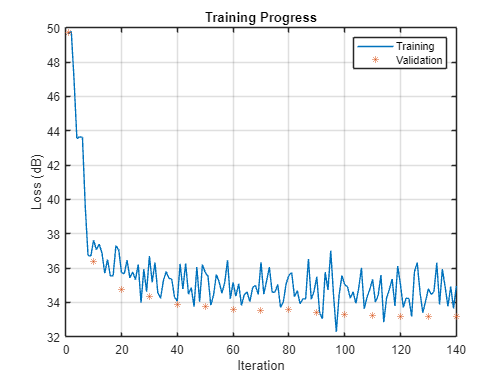

helperPlotTrainingProgress(info)

imgs_test  = zeros(376,512,3,25,'single');
resps_test = zeros(376,512,3,25,'single');

for ind = 1:33
    % Read the image data using imread and store it in the corresponding slice
    imgs_test(:,:,:,ind) = im2single(imresize(imread("New radar dataset/test/Input/Clutter ("+ind+").png"), [376, 512]));
    resps_test(:,:,:,ind) = im2single(imresize(imread("New radar dataset/test/Output/noClutter ("+ind+").png"), [376, 512]));
end

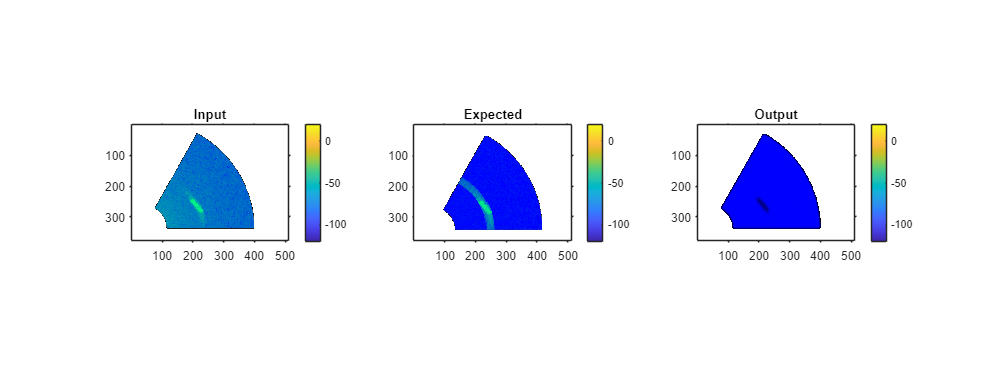

evalSet = 5;
helperPlotEvalResults(imgs_test(:,:,:,evalSet),resps_test(:,:,:,evalSet),net);